dla toru U-Y

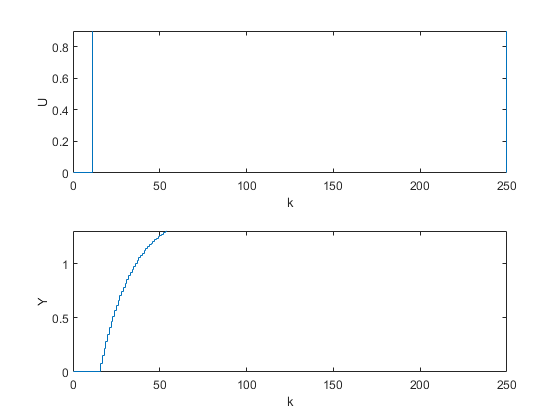


Upp = 0;
Ypp = 0;
Zpp = 0;
Us = 1; % jeden ze skokow z zad2
Tp = 0.5;
imax = 250;
T = 1:imax;
Y = zeros(1, imax);
U = zeros(1, imax+1);
Z = zeros(1, imax);
Y(1:11) = Ypp;
Z(1:11) = Zpp;
U(1:11) = Upp;
U(12:imax) = Us;


for k=12:imax
    Y(k)=symulacja_obiektu2y_p2(U(k-5),U(k-6),Z(k-3),Z(k-4),Y(k-1),Y(k-2));
end

f1 = figure;
subplot(2,1,1);
stairs(0:length(U)-1,U);
xlabel('k');
ylabel('U');
ylim([0 0.9])
subplot(2,1,2);
stairs(0:length(Y)-1, Y);
ylim([0 1.3])
xlabel('k');
ylabel('Y');
hold off;

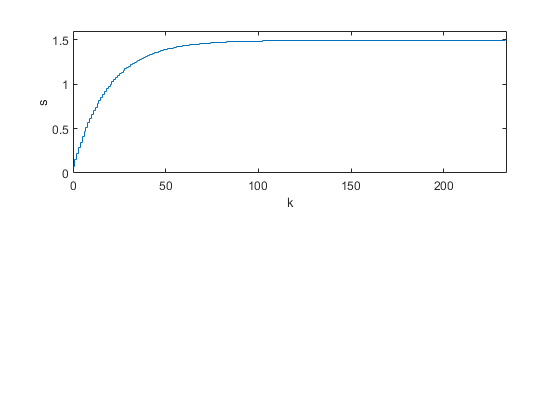


d1 = 16; % pierwszy skok z zad2 dla toru U-Y

% D = 116 - 16; % to jest dobrze odczytane z wykresu z zad2
dU = Us - Upp;

s = zeros(1,imax-d1);
for k = 1:imax-d1
    s(k)=(Y(k+d1)-Ypp)/dU;
end

f2 = figure;
subplot(2,1,1);
stairs(0:length(s)-1, s);
axis([0 imax-d1 0 1.6]);
xlabel('k');
ylabel('s');
hold off;

dla toru Z-Y

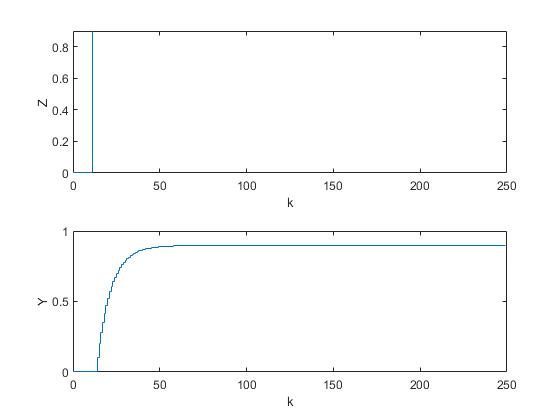

Upp = 0;
Ypp = 0;
Zpp = 0;
Zu = 0;
Zs = 1;
Tp = 0.5;
imax = 250;
T = 1:imax;
Y = zeros(1, imax);
U = zeros(1, imax+1);
Z = zeros(1, imax);
Y(1:11) = Ypp;
Z(1:11) = Zpp;
U(1:11) = Upp;
Z(12:imax) = Zs;
U(12:imax) = Zu;

for k=12:imax
    Y(k)=symulacja_obiektu2y_p2(U(k-5),U(k-6),Z(k-3),Z(k-4),Y(k-1),Y(k-2));
end

f3 = figure;
subplot(2,1,1);
stairs(0:length(Z)-1,Z);
xlabel('k');
ylabel('Z');
ylim([0 0.9])
subplot(2,1,2);
stairs(0:length(Y)-1, Y);
xlabel('k');
ylabel('Y');
hold off;

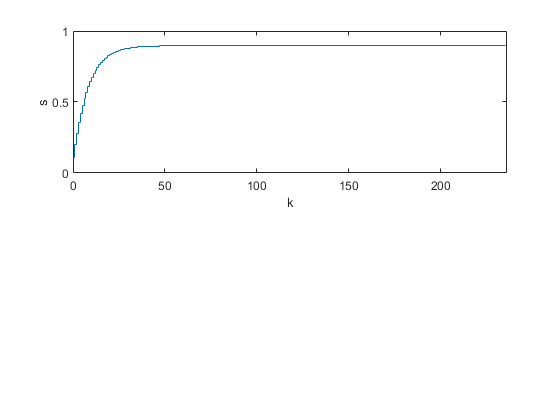


d1 = 14;  % nie jestem pewna skąd wziąć prawidłową wartość tego, 
% wzielam jako pierwszy skok z zad2 dla toru Z-Y

% D = 75 - 14; % to jest dobrze odczytane z wykresu z zad2, ale nie wiem
% czy do czegos sie przyda

dZ = Zs - Zpp;

sz = zeros(1,imax-d1);
for k = 1:imax-d1
    sz(k)=(Y(k+d1)-Ypp)/dZ;
end

f4 = figure;
subplot(2,1,1);
stairs(0:length(sz)-1, sz);
axis([0 imax-d1 0 1]);
xlabel('k');
ylabel('s');